# Energy Prices - ANOVA

## 1.

Load the variables `Date`, `Hour`, and `ElecPrice` from the file `ElecSeries.mat`.

load('ElecSeries.mat','Date','Hour','ElecPrice');

## 2.

Perform a 1-way ANOVA on the electricity prices grouped by the hour of the day. Identify possible subgroups using  the function `multcompare`.

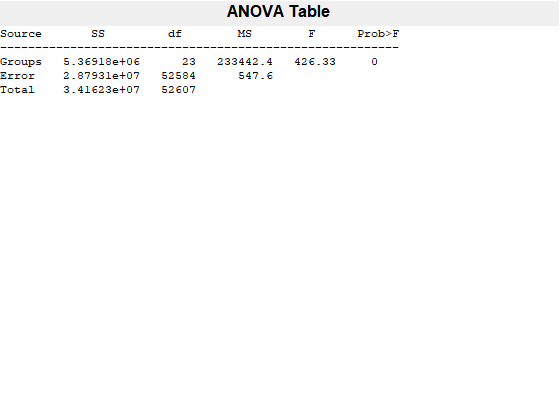

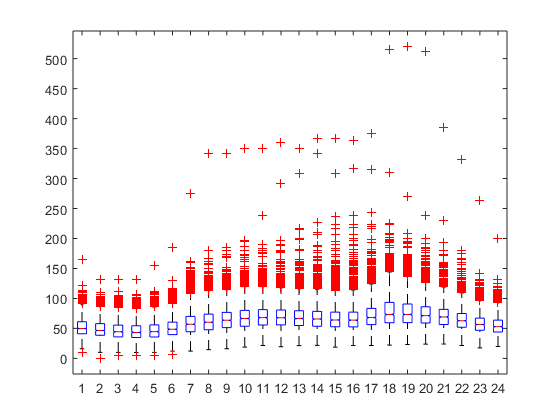

[~,~,stats] = anova1(ElecPrice, Hour);

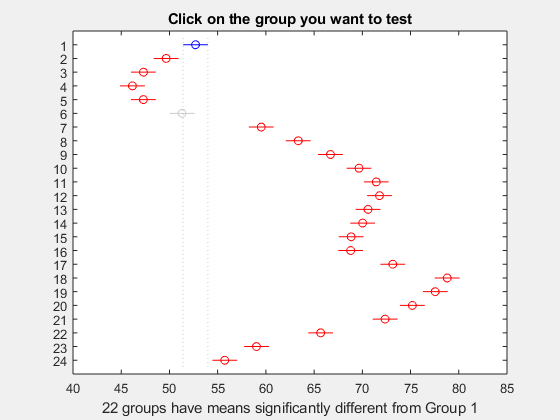

ans =     1.0000    2.0000    0.4788    3.0497    5.6206    0.0038
    1.0000    3.0000    2.8273    5.3982    7.9691    0.0000
    1.0000    4.0000    3.9713    6.5422    9.1131    0.0000
    1.0000    5.0000    2.8378    5.4087    7.9796    0.0000
    1.0000    6.0000   -1.1735    1.3974    3.9683    0.9531
    1.0000    7.0000   -9.3842   -6.8133   -4.2424    0.0000
    1.0000    8.0000  -13.2188  -10.6479   -8.0770    0.0000
    1.0000    9.0000  -16.5616  -13.9906  -11.4197    0.0000
    1.0000   10.0000  -19.5201  -16.9492  -14.3783    0.0000
    1.0000   11.0000  -21.3097  -18.7388  -16.1679    0.0000


figure('Visible','on')
multcompare(stats)

## 3.

Perform a 1-way ANOVA on the electricity prices grouped by the day of the week. Identify possible subgroups using  the function `multcompare`.

**Hint**: There is a `weekday` function that converts numeric date information into weekday information.

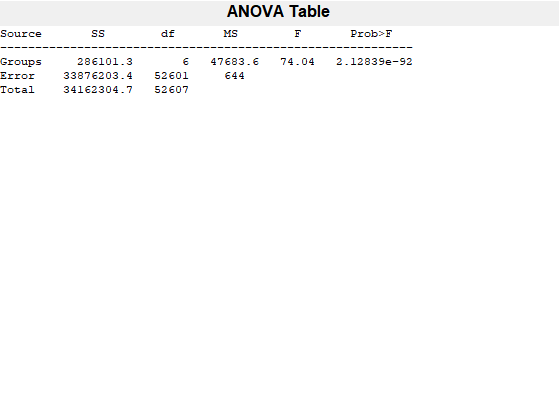

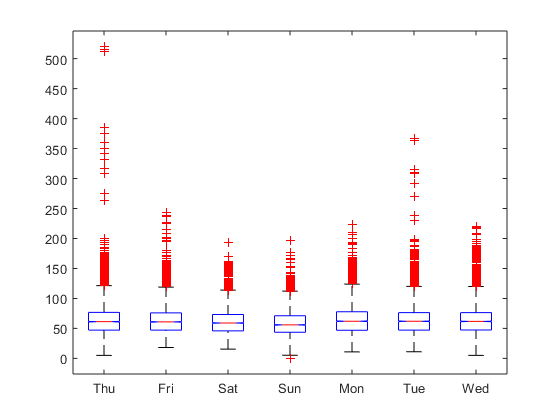

[~,days] = weekday(Date);
[~,~,stats] = anova1(ElecPrice, days);

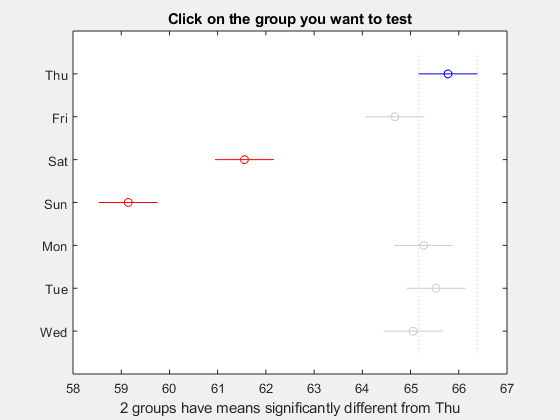

ans =     1.0000    2.0000   -0.1171    1.1027    2.3226    0.1072
    1.0000    3.0000    3.0005    4.2204    5.4403    0.0000
    1.0000    4.0000    5.4115    6.6314    7.8513    0.0000
    1.0000    5.0000   -0.7167    0.5032    1.7231    0.8882
    1.0000    6.0000   -0.9721    0.2477    1.4676    0.9969
    1.0000    7.0000   -0.4945    0.7254    1.9453    0.5799
    2.0000    3.0000    1.8968    3.1177    4.3385    0.0000
    2.0000    4.0000    4.3078    5.5286    6.7495    0.0000
    2.0000    5.0000   -1.8204   -0.5996    0.6213    0.7756
    2.0000    6.0000   -2.0758   -0.8550    0.3659    0.3738


figure('Visible','on')
multcompare(stats)

## 4.

Perform a 2-way ANOVA on the electricity prices grouped by the hour of the day and the day of the week. Visualize the subgroups in different dimensions using  the function `multcompare`.

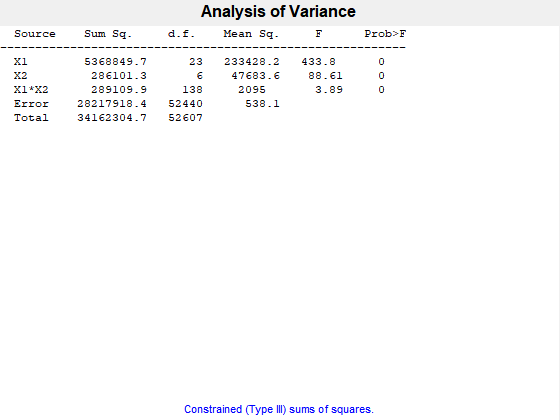

[~,~,stats] = anovan(ElecPrice, {Hour, days}, ...
    'model','interaction');

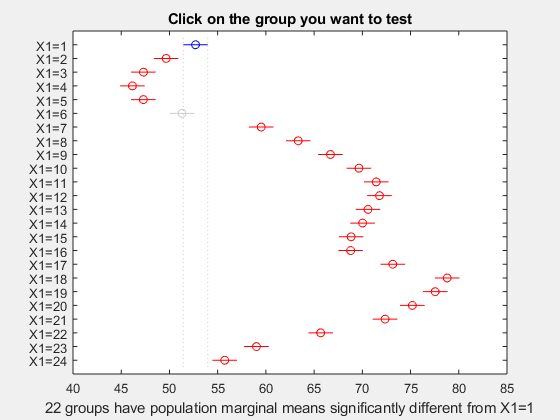

ans =     1.0000    2.0000    0.5011    3.0497    5.5983    0.0032
    1.0000    3.0000    2.8496    5.3981    7.9467    0.0000
    1.0000    4.0000    3.9936    6.5422    9.0908    0.0000
    1.0000    5.0000    2.8603    5.4089    7.9575    0.0000
    1.0000    6.0000   -1.1503    1.3983    3.9469    0.9482
    1.0000    7.0000   -9.3596   -6.8111   -4.2625    0.0000
    1.0000    8.0000  -13.1942  -10.6456   -8.0970    0.0000
    1.0000    9.0000  -16.5377  -13.9891  -11.4405    0.0000
    1.0000   10.0000  -19.4966  -16.9480  -14.3994    0.0000
    1.0000   11.0000  -21.2864  -18.7378  -16.1893    0.0000


figure('Visible','on')
multcompare(stats,'dimension',1)